data=readtable("GlobalLandTemperatures_GlobalLandTemperaturesByMajorCity.csv");
%removes rown with more than 3 unknown values, efficient but not feasable
%{
for rownum=1:574223
    if(rownum==1)
        data2=data(1,:);
    end
    if(sum(ismissing(data(rownum,:)))<3)
        data2=[data2;data(rownum,:)];
    end
end
%}
%null value equal to previous value
data1=data;
data1=fillmissing(data1,"previous");
%checking for number of outliers in data
ans=sum(isoutlier(data1(:,2),"mean"));
ans=sum(isoutlier(data1(:,3),"mean"));
%making a new dataset by filling outliers using the linear method
data3=filloutliers(data1(:,2:3),"linear");
data3=[data1(:,1),data3,data1(:,4)];
%unrelated to the objective but here is the normalized values of the
%average temperature uncertainity
normalized = normalize(data3(:,3),'norm',Inf);
%this smoothens the data but decreases the accuracy of the data
smoothdata(data3(:,2),"gaussian");
%to check the number of entries for each country
countrygroups=groupcounts(data1,"Country");
%divided data into groups of each country and found the average temperature
%over the years and descritized them based on it
[groups,key]=findgroups(data.Country);
avgtemp=splitapply(@mean,data1.AverageTemperature,groups);
group=groupcounts(data1,"Country");
group=group(:,1);
avgtemp=array2table(avgtemp);
avgtemp=[group,avgtemp];
discreteclimate=discretize(avgtemp.avgtemp,7);
%summary of the entire data
summary(data1)

Variables:

    dt: 239177×1 datetime

        Values:

            Min       1743-11-01
            Median    1914-02-01
            Max       2013-09-01

    AverageTemperature: 239177×1 double

        Values:

            Min       -26.772 
            Median     20.486 
            Max        38.283 

    AverageTemperatureUncertainty: 239177×1 double

        Values:

            Min          0.04 
            Median      0.631 
            Max        14.037 

    City: 239177×1 cell array of character vectors

    Country: 239177×1 cell array of character vectors

    Latitude: 239177×1 cell array of character vectors

    Longitude: 239177×1 cell array of character vectors



%converting the date into datetime format
data4=data1;
datetime(data4.dt,"InputFormat",'uuuu-MM-dd');
data4.dt=datetime(data4.dt,"InputFormat",'uuuu-MM-dd');
%adding groups to the dataset to categorize the data easily
data4=[data4,array2table(groups)];
%max temperatures recorded over the years
[~,maxidx]=maxk(data4.AverageTemperature,10);
maxtemptable=data4(maxidx,:);
%min temperatures recorded over the years
[~,minidx]=mink(data4.AverageTemperature,10);
mintemptable=data4(minidx,:);

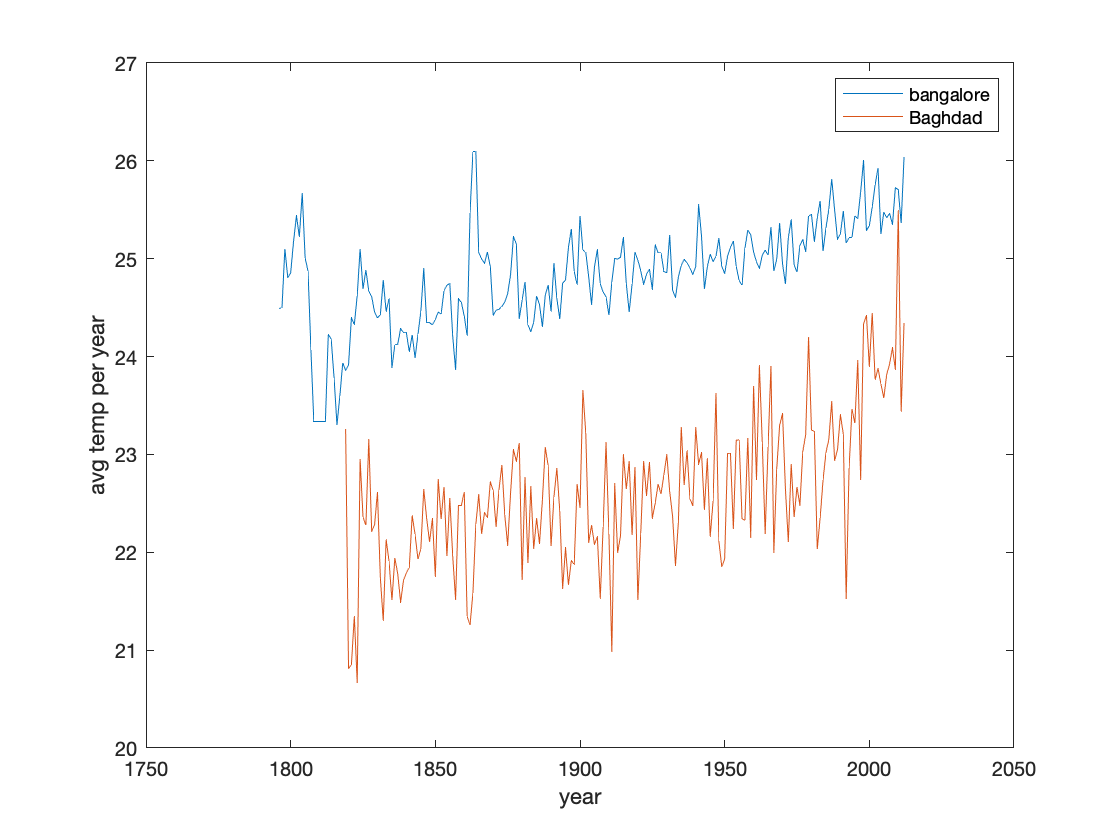

%calculates the average temperature for every year of specific cities
%and plots them against year
datplot1=data4(data4.City=="Bangalore",:);
test=year(datplot1.dt);
test=unique(test);
test(:,2)=0;
for i=1:height(datplot1)
    test(find(test(:,1)==year(table2array(datplot1(i,"dt")))),2)=test(find(test(:,1)==year(table2array(datplot1(i,"dt")))),2)+table2array(datplot1(i,"AverageTemperature"));
end
test(end,:)=[];
test(:,2)=test(:,2)/12;
plot(test(:,1),test(:,2))
hold on
datplot1=data4(data4.City=="Baghdad",:);
test=year(datplot1.dt);
test=unique(test);
test(:,2)=0;
for i=1:height(datplot1)
    test(find(test(:,1)==year(table2array(datplot1(i,"dt")))),2)=test(find(test(:,1)==year(table2array(datplot1(i,"dt")))),2)+table2array(datplot1(i,"AverageTemperature"));
end
test(end,:)=[];
test(:,2)=test(:,2)/12;
plot(test(:,1),test(:,2))
hold off
legend("Bangalore","Baghdad")
xlabel("year")
ylabel("avg temp per year")

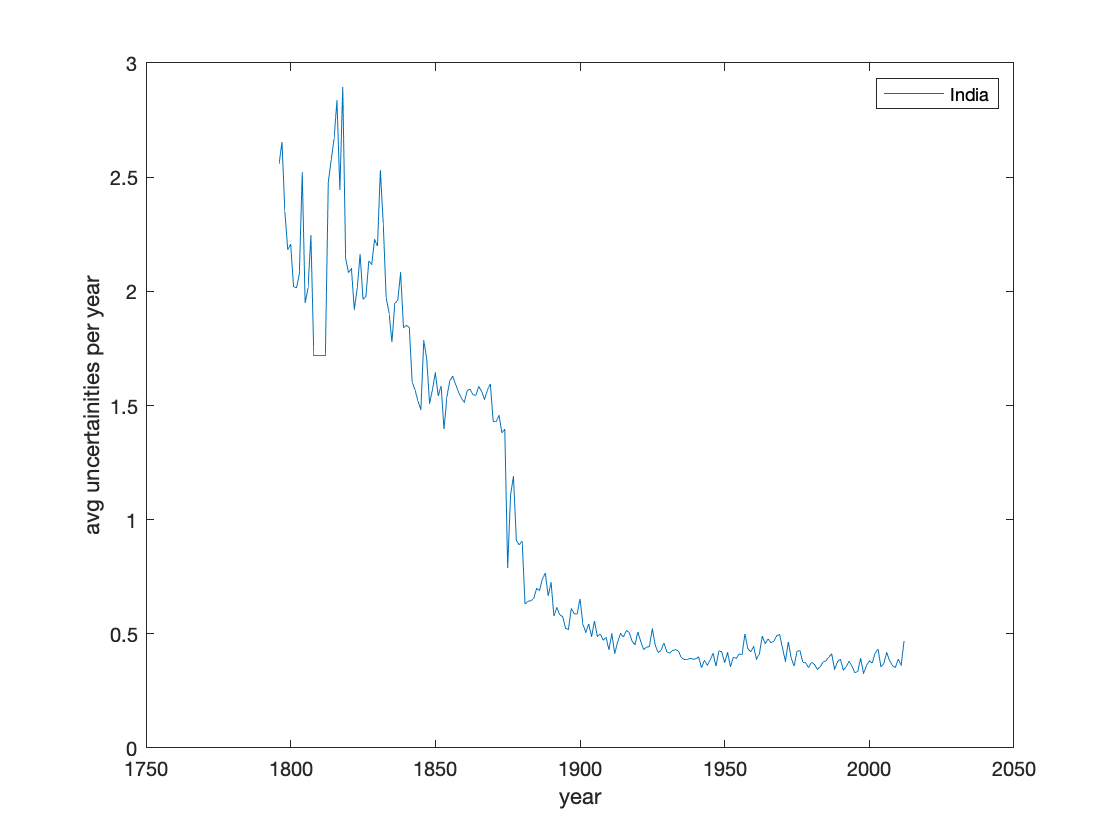


%avg uncertainities per year of certain city
datplot1=data4(data4.Country=="India",:);
test=year(datplot1.dt);
test=unique(test);
test(:,2:3)=0;
for i=1:height(datplot1)
    test(find(test(:,1)==year(table2array(datplot1(i,"dt")))),2)=test(find(test(:,1)==year(table2array(datplot1(i,"dt")))),2)+table2array(datplot1(i,"AverageTemperatureUncertainty"));
    test(find(test(:,1)==year(table2array(datplot1(i,"dt")))),3)=test(find(test(:,1)==year(table2array(datplot1(i,"dt")))),3)+1;
end
test(end,:)=[];
test(:,2)=test(:,2)./test(:,3);
plot(test(:,1),test(:,2),'LineWidth',1.5)
legend("India")
xlabel("year")
ylabel("avg uncertainities per year")

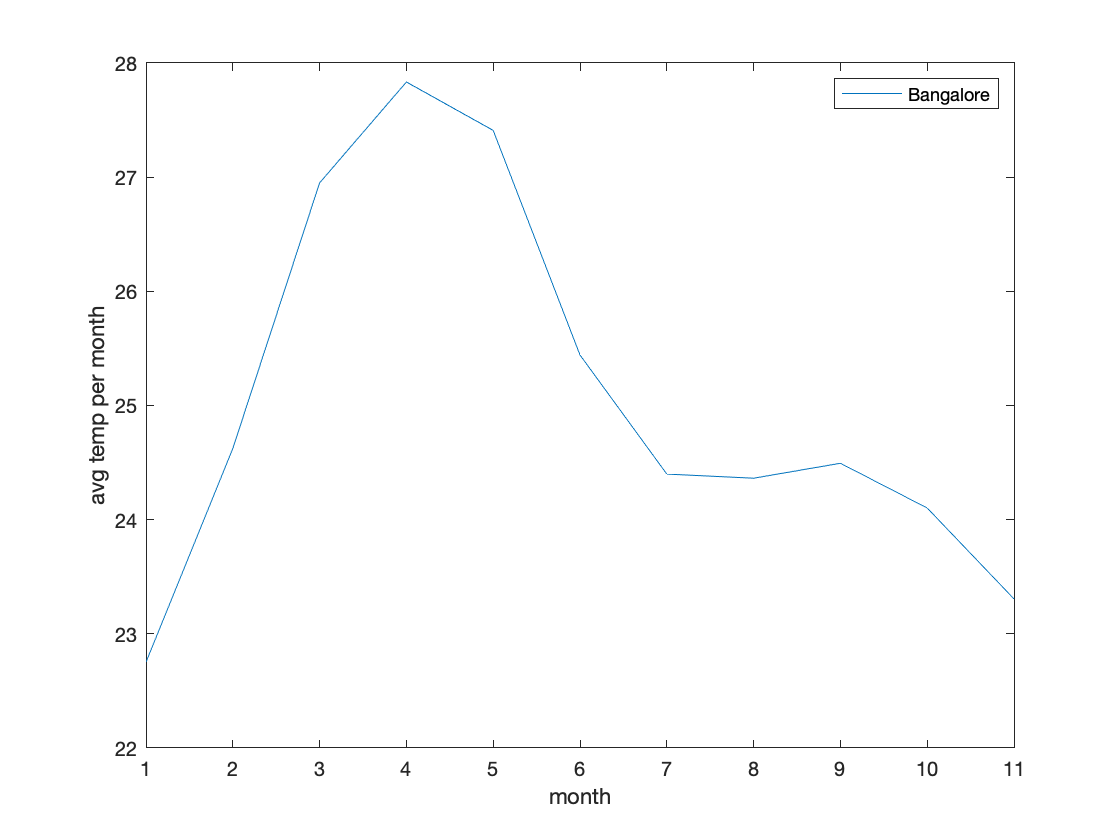


%seasonal anlysis of temperature over the years
datplot1=data4(data4.City=="Bangalore",:);
test=month(datplot1.dt);
test=unique(test);
test(:,2:3)=0;
for i=1:height(datplot1)
    test(find(test(:,1)==month(table2array(datplot1(i,"dt")))),2)=test(find(test(:,1)==month(table2array(datplot1(i,"dt")))),2)+table2array(datplot1(i,"AverageTemperature"));
    test(test(:,1)==month(table2array(datplot1(i,"dt"))),3)=test(find(test(:,1)==month(table2array(datplot1(i,"dt")))),3)+1;
end
test(end,:)=[];
test(:,2)=test(:,2)./test(:,3);
plot(test(:,1),test(:,2),'LineWidth',1.5)
legend("Bangalore")
xlabel("month")
ylabel("avg temp per month")

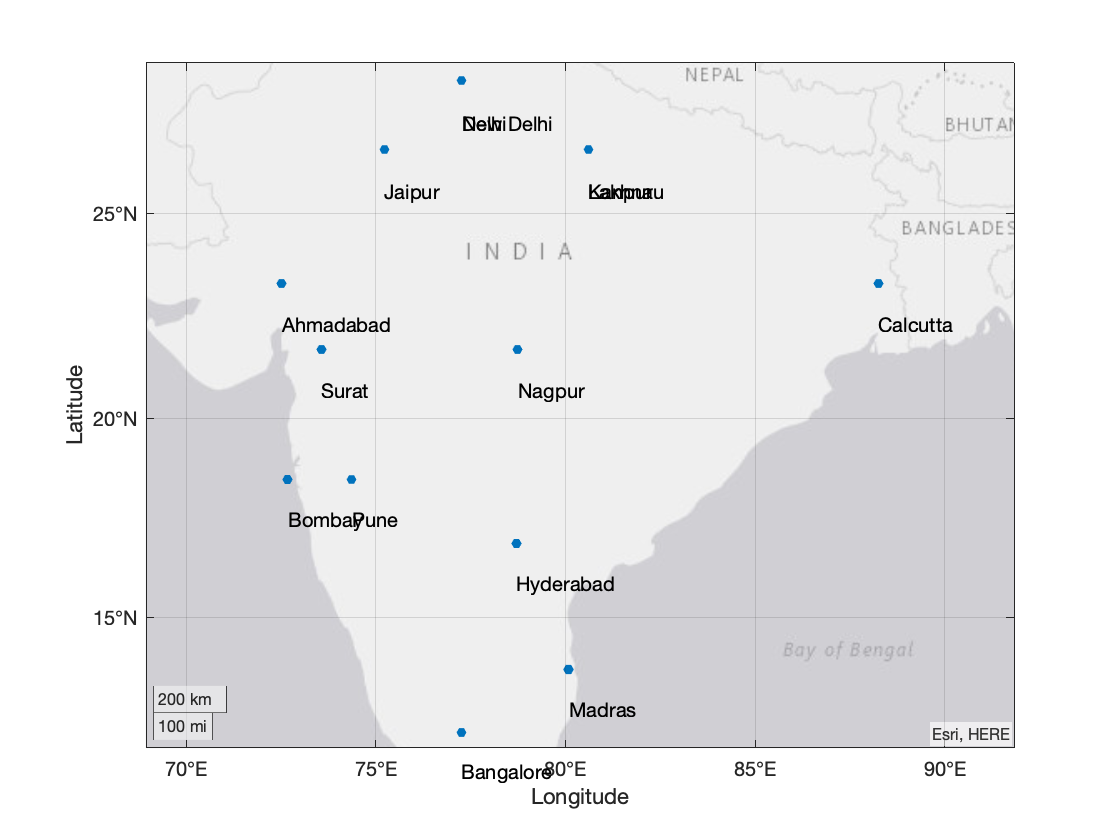


%geoscatter plot indicating the temperatures wrt to their size
datplot1=data4(data4.Country=="India",:);
[citygroups,citykey]=findgroups(datplot1.City);
datplot1(:,9)=array2table(citygroups);
test=datplot1(:,4:7);
test=unique(test);
testkey=(1:height(test)).';
testkey(:,2:3)=0;
for i=1:height(datplot1)
    testkey(find(testkey(:,1)==table2array(datplot1(i,"Var9"))),2)=testkey(find(testkey(:,1)==table2array(datplot1(i,"Var9"))),2)+table2array(datplot1(i,"AverageTemperature"));
    testkey(find(testkey(:,1)==table2array(datplot1(i,"Var9"))),3)=testkey(find(testkey(:,1)==table2array(datplot1(i,"Var9"))),3)+1;
end
testkey(:,2)=testkey(:,2)./testkey(:,3);
% converts the given longgitude and latitude to a usable form
for i=1:height(test)
    temp=str2double(regexp(string(test{i,3}),'[\d.]+','match'));
    latnew(i)=temp;
    temp=str2double(regexp(string(test{i,4}),'[\d.]+','match'));
    longnew(i)=temp;
end
test(:,5)=array2table(latnew.');
test(:,6)=array2table(longnew.');
geoscatter(test{:,5},test{:,6},testkey(:,2),"filled")
text(test{:,5}-1,test{:,6},test{:,1});

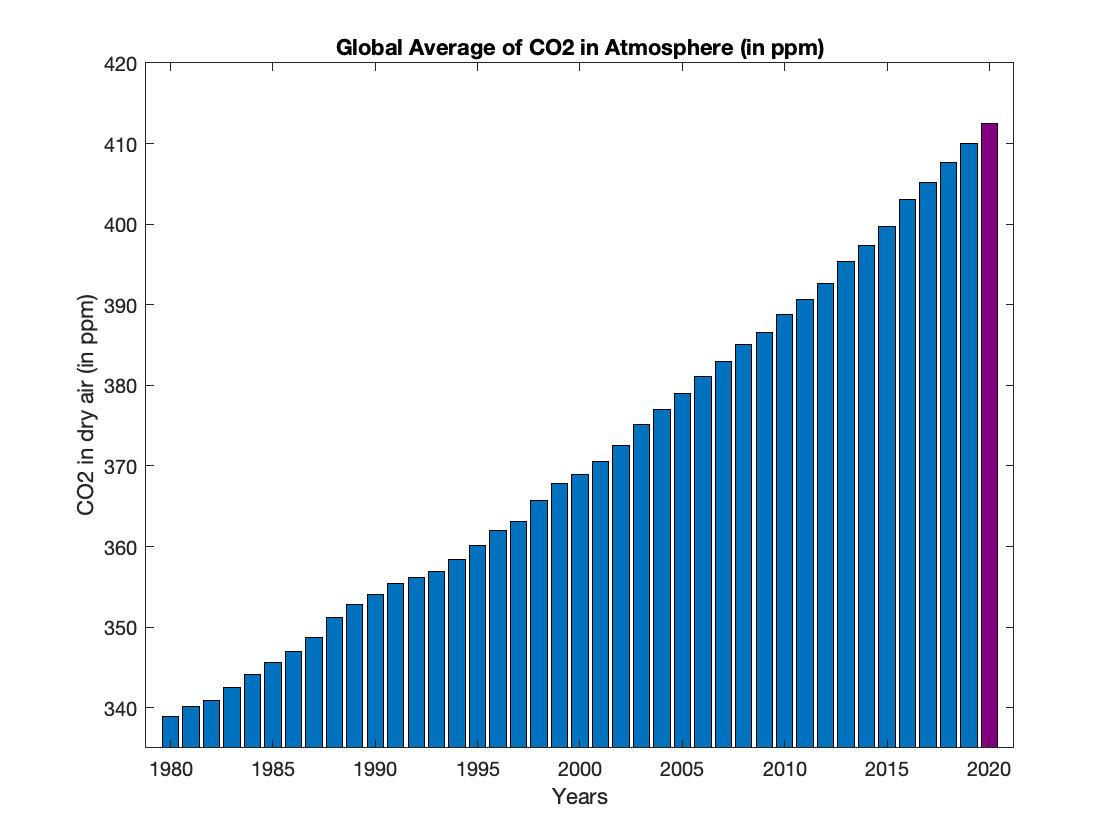

%Rise of global CO2 since 1980
annualMean = readtable("c02-globalmeanannual.txt","FileType","text");
x = annualMean.year;
y = annualMean.mean;
b = bar(x,y);
% set the limits of the y-axis to get effective depiction
ylim([335 420]);
%Setting the facecolor to flat, this allows us to change the colour of the last bar (YEAR 2020) 
b.FaceColor = 'flat';
b.CData(41,:) = [0.5 0 0.5];    % sets the colour of the last bar based on the RGB triplet
% Title and the labels
title("Global Average of CO2 in Atmosphere (in ppm)");
ylabel('CO2 in dry air (in ppm)');
xlabel("Years");

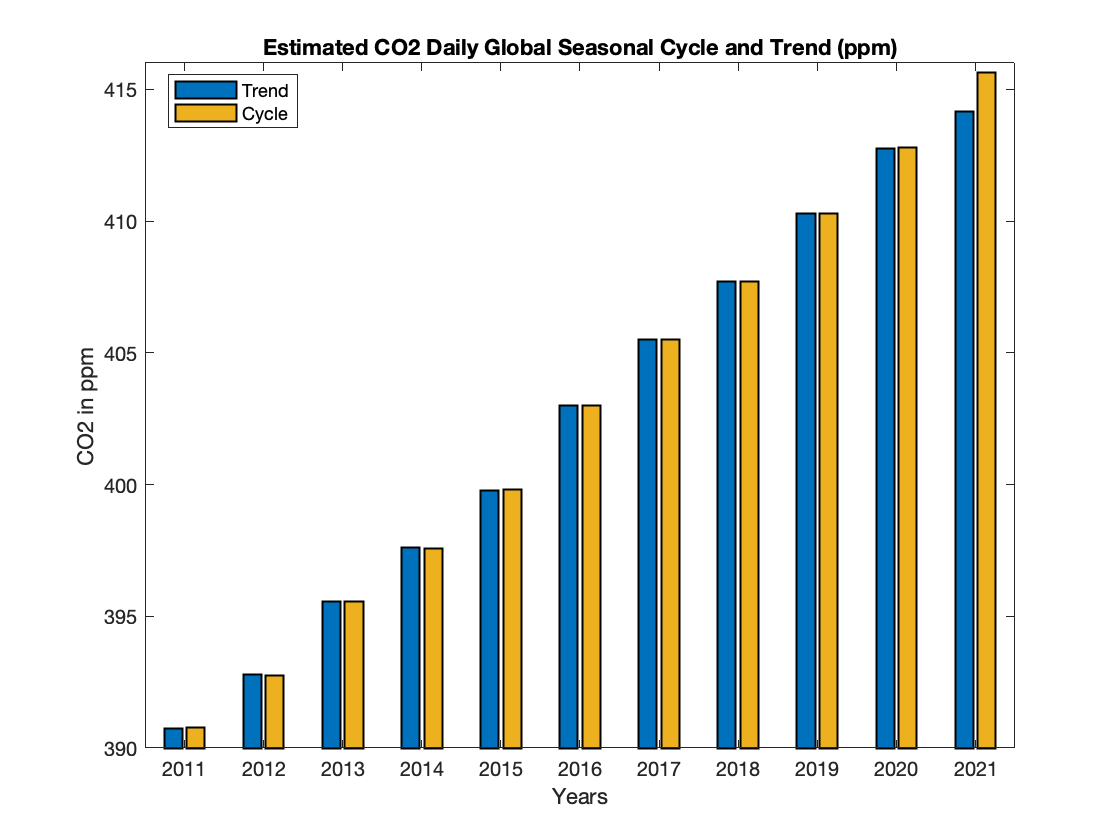

%Global trend in the increase of CO2
globalTrend = readtable("CO2-gloabaltrend.txt","FileType","text","CommentStyle","#");
%Explicitly set variable names (Column Names)
globalTrend.Properties.VariableNames = {'Year','Month','Day','Cycle','Trend'};
%group the rows based on the Variable 'Year'
yeargrp = findgroups(globalTrend.Year);
%The below code finds the mean of the variables 'Trend' and 'Cycle'
%based on the groups divided in the above step.
meanTrend = splitapply(@mean,globalTrend.Trend,yeargrp);
meanCycle = splitapply(@mean, globalTrend.Cycle,yeargrp);
yeararr = [2011:2021]';
y = [meanTrend meanCycle];
%plots grouped Bar plot
b = bar(yeararr,y,"LineWidth",1);
%set the colour of the second group in the bar plot
b(2).FaceColor = [0.9290 0.6940 0.1250];
% set the limits of the y-axis to get effective depiction
ylim([390 416]);
% Title and the labels
title('Estimated CO2 Daily Global Seasonal Cycle and Trend (ppm)')
legend('Trend','Cycle',"Location","best");
ylabel("CO2 in ppm");
xlabel("Years");

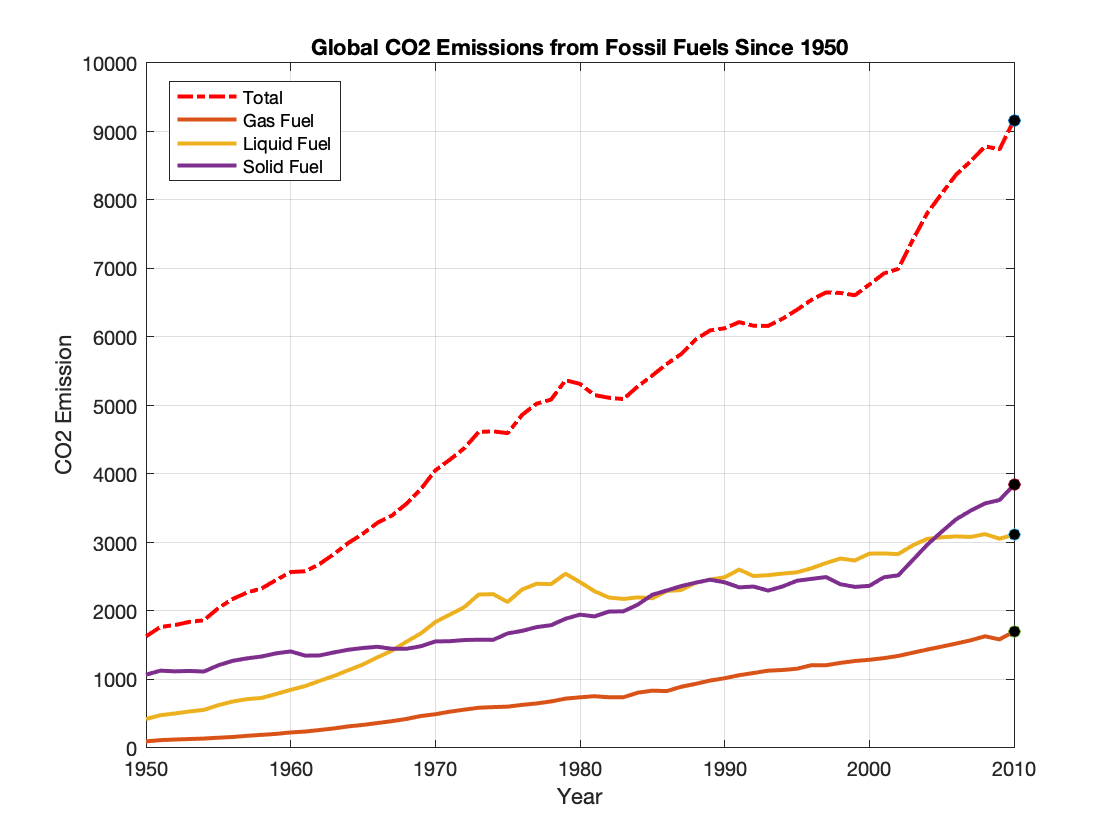

%CO2 emissions due to fossil fuels
fossilFuels = readtable("CO2-fossilfuels.csv","FileType","text","VariableNamingRule","preserve");
%Explicitly set variable names (Column Names)
colHeaders = ["Year","total","GasFuel","LiquidFuel","SolidFuel","Cement","GasFlaring","PerCapita"];
fossilFuels.Properties.VariableNames = colHeaders;
%Cleaning the dataset by removing the missing values.
fossilFuels = rmmissing(fossilFuels);
x = fossilFuels.Year;
y1 = fossilFuels.GasFuel;
y2 = fossilFuels.LiquidFuel;
y3 = fossilFuels.SolidFuel;
y4 = fossilFuels.total;
%plotting the first line plot : Total Fuels
plot(x,y4,'r-.','LineWidth',2);
%setting hold on to allow multiple plots to be plotted
%grid on to show the grids
grid on;
hold on;
%plotting the remaining three line plots
plot(x,y1,'LineWidth',2);   % -> Gas Fuel
plot(x,y2,'LineWidth',2);   % -> Liquid Fuel
plot(x,y3,'LineWidth',2);   % -> Solid Fuel
%the below code sets the Marker that runs through the line plots
%plot(x(1),y(1)) sets the marker initially at the start of each line plot
p1 = plot(x(1),y1(1),'o','MarkerFaceColor',[0 0 0]);
p2 = plot(x(1),y2(1),'o','MarkerFaceColor',[0 0 0]);
p3 = plot(x(1),y3(1),'o','MarkerFaceColor',[0 0 0]);
p4 = plot(x(1),y4(1),'o','MarkerFaceColor',[0 0 0]);
hold off;
axis manual
%Title and the labels
title('Global CO2 Emissions from Fossil Fuels Since 1950');
legend('Total','Gas Fuel','Liquid Fuel','Solid Fuel','Location',"best");
ylabel('CO2 Emission');
xlabel('Year')
%For loop runs for each meaker where it draws the marker at each x-value
%its corresponding points on y-axis.
%Loop for Gas Fuel
for k1 = 1:length(x)
    p1.XData = x(k1);
    p1.YData = y1(k1);
    drawnow
end
%Loop for Liquid Fuel
for k2 = 1:length(x)
    p2.XData = x(k2);
    p2.YData = y2(k2);
    drawnow
end
%Loop for Solid Fuel
for k3 = 1:length(x)
    p3.XData = x(k3);
    p3.YData = y3(k3);
    drawnow
end
%Loop for Total Fuel
for k4 = 1:length(x)
    p4.XData = x(k4);
    p4.YData = y4(k4);
    drawnow
end

%CO2 Emissions by Nations
%file contains emission data of all countries -> 17232 observations
nations = readtable("CO2-emissionbynation.csv","FileType","text",'VariableNamingRule',"preserve");
nations

nations = 17232×10 table
    Year         Country          Total    Solid Fuel    Liquid Fuel    Gas Fuel    Cement    Gas Flaring    Per Capita    Bunker fuels (Not in Total)
    ____    __________________    _____    __________    ___________    ________    ______    ___________    __________    ___________________________

    1751    {'UNITED KINGDOM'}    2552        2552            0            0          0            0             0                      0             
    1752    {'UNITED KINGDOM'}    2553        2553            0            0          0            0             0                      0             
    1753    {'UNITED KINGDOM'}

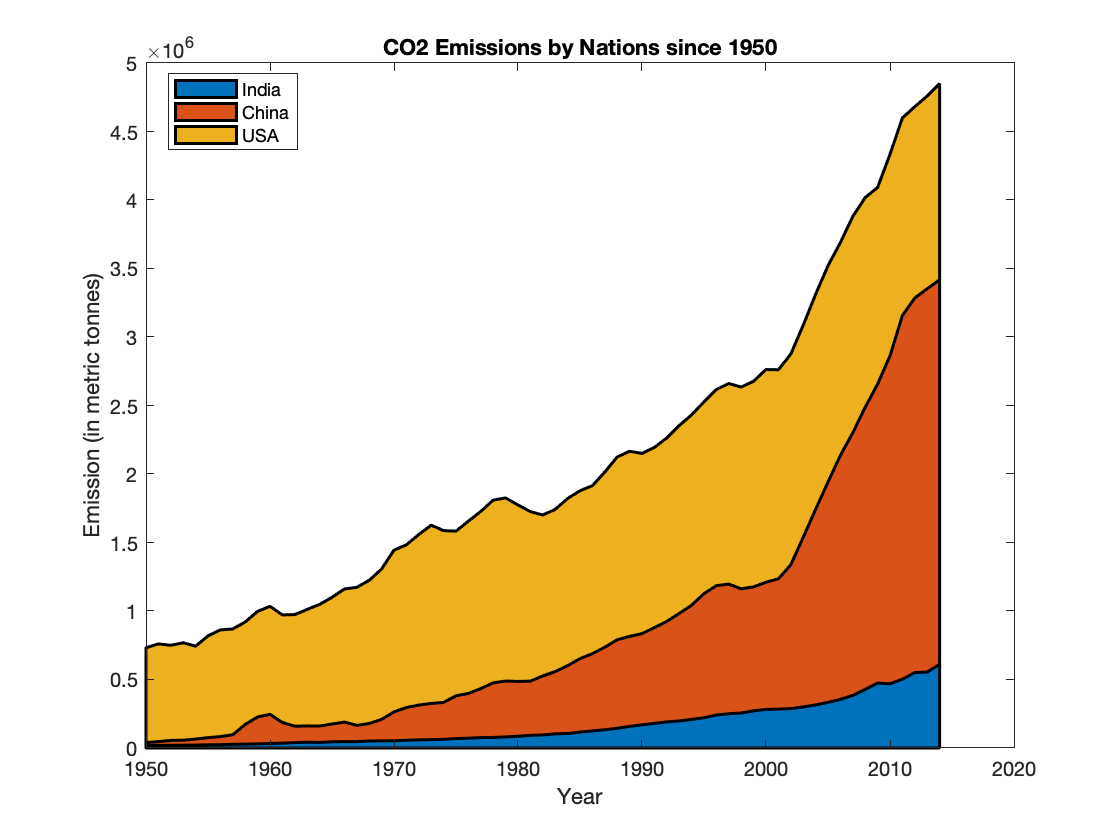

%categorise the data based on the 'Country'
nations.Country = categorical(nations.Country);
%pick out only the observations corresponding to India, USA, China
india = nations(nations.Country=='INDIA',:);
usa = nations(nations.Country=='UNITED STATES OF AMERICA',:);
china = nations(nations.Country=='CHINA (MAINLAND)',:);
%Sort and retain the data based on the year 1950
india1950 = india(india.Year>=1950,:);
usa1950 = usa(usa.Year>=1950,:);
china1950 = china(china.Year>=1950,:);
%create a 3-column matrix with the above sorted values and the variale
%'Total'
cols = [india1950.Total,china1950.Total,usa1950.Total];
% plot an area plot
area(india1950.Year,cols,'LineWidth',1.5)
%Titles and the labels
title('CO2 Emissions by Nations since 1950');
legend('India','China','USA','Location',"best");
xlabel('Year');
ylabel('Emission (in metric tonnes)');